## C

fs = 8000;
duration = 0.1;
gap = 0.1;

[t_total,z] = generate_wave({"1","5","9","D"},fs,duration,gap);


### Filter Response

passband_ripple = 0.2;             % Pass band ripple in dB
stopband_attenuation = 50;         % Stop band attenuation in dB
passband_freq = [0 1650];          % Pass band frequency range in Hz
stopband_freq = [2350 3999];       % Stop band frequency range in Hz
sampling_freq = fs;              % Sampling frequency in Hz

% Normalize the cutoff frequencies
passband_freq_norm = passband_freq / (sampling_freq / 2);
normalized_stopband = stopband_freq / (sampling_freq / 2);
% Design the Chebyshev Type II filter
[filtered_signal, b, a] = low_pass1(z, fs);

#### Pole Zero Diagram & Frequency Response

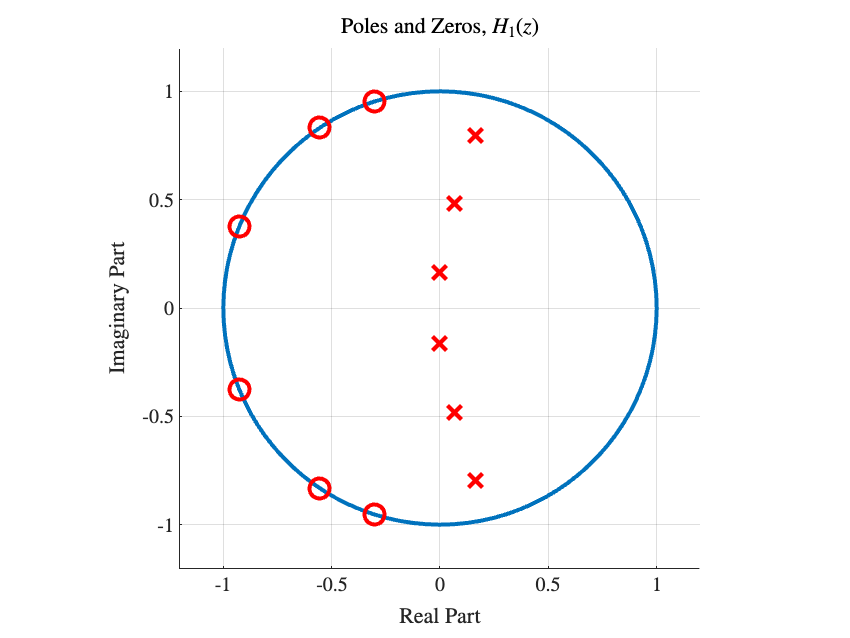

% Plot the pole-zero diagram and frequency response

figure;
hold on
plot(exp(1i*2*pi*(0:0.01:1)),'linewidth',2)
plot(roots(b),'ro','linewidth',2,'markersize',10)
plot(roots(a),'rx','linewidth',2,'markersize',10)
grid on
axis('square')
axis([-1.2 1.2 -1.2 1.2])
title('Poles and Zeros, $H_1(z)$')
xlabel('Real Part')
ylabel('Imaginary Part')
hold off

exportgraphics(gcf, 'TeX/images/4C_PoleZero.eps');

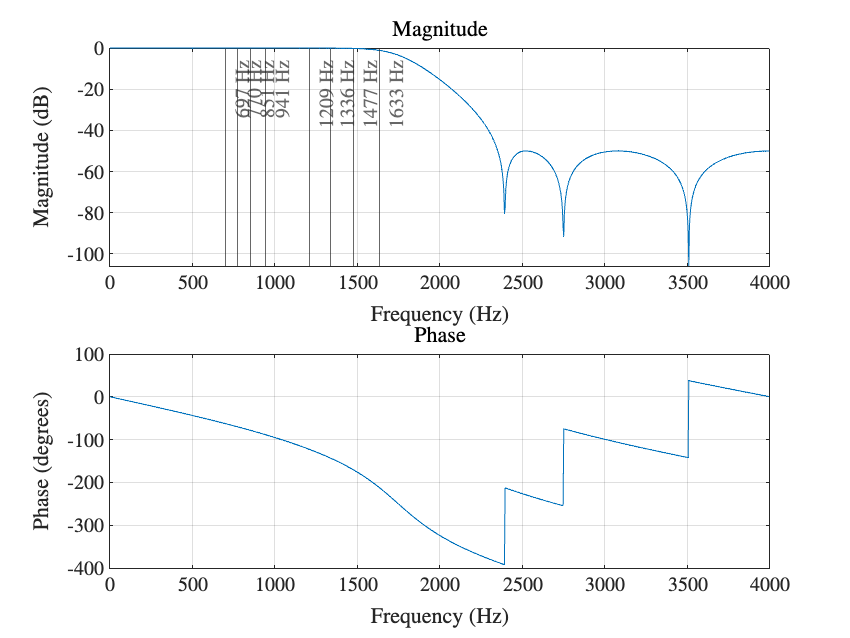


figure()

% Use freqz for frequency response plot
hold on
freqz(b, a, 1024, fs);
xline(697,'Label','697 Hz');
xline(770,'Label','770 Hz');
xline(852,'Label','851 Hz');
xline(941,'Label','941 Hz');
xline(1209,'Label','1209 Hz');
xline(1336,'Label','1336 Hz');
xline(1477,'Label','1477 Hz');
xline(1633,'Label','1633 Hz');
hold off

exportgraphics(gcf, 'TeX/images/4C_FreqResponse.eps');

#### Filter and Downsample to 4000Hz

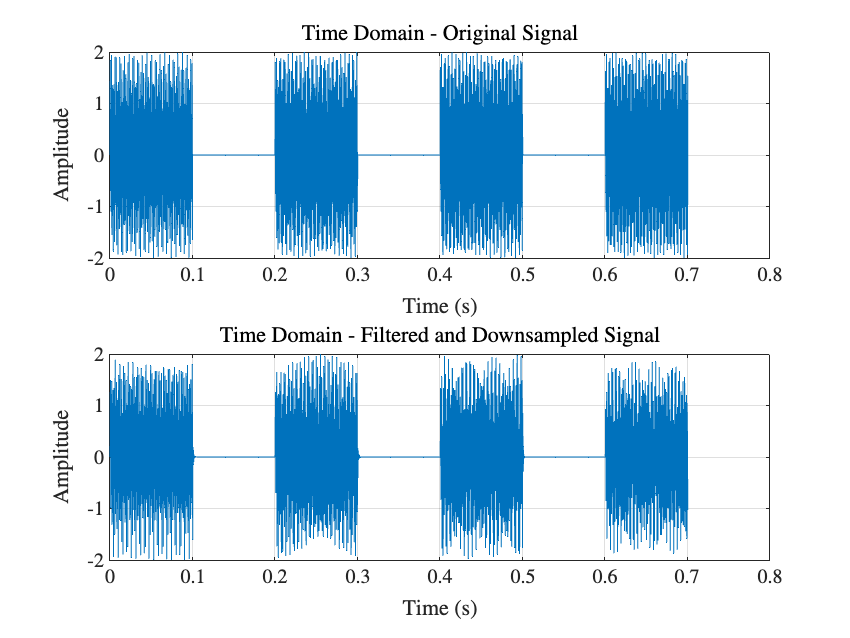

downsampled_signal = downsample(filtered_signal, 2);

% Compute the Spectrum of the output signal
input_spectrum = fft(z);
output_spectrum = fft(downsampled_signal);

% Plot the time domain waveform
figure;
subplot(2, 1, 1);
plot(t_total, z, 'DisplayName', 'Original Signal');
title('Time Domain - Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on

subplot(2,1,2)
plot(t_total(1:2:end), downsampled_signal, 'DisplayName', 'Filtered Signal');
grid on
title('Time Domain - Filtered and Downsampled Signal');
xlabel('Time (s)');
ylabel('Amplitude');

exportgraphics(gcf, 'TeX/images/4C_TimeDomainComparison.eps');

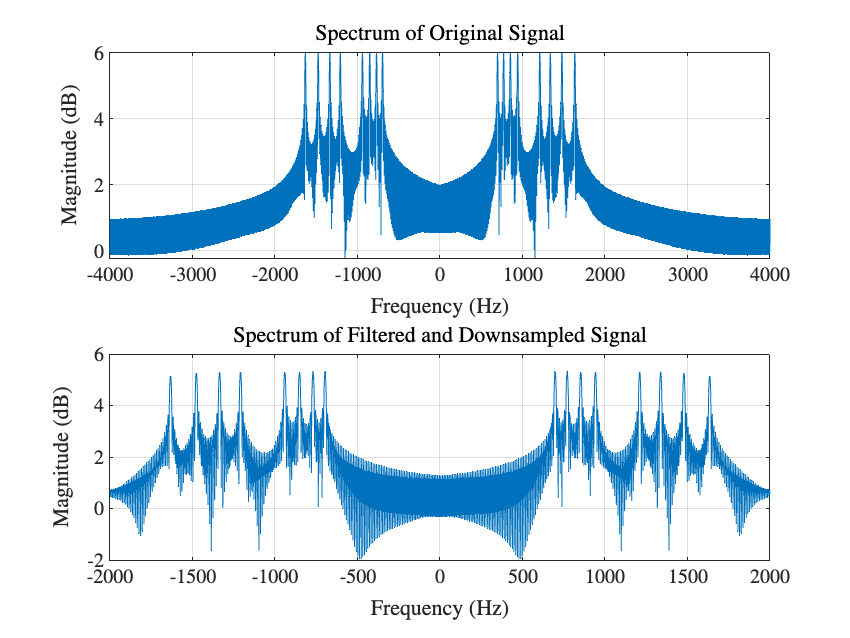


% Plot the Spectrum of the output signal
figure()
subplot(2,1,1)
f_output = linspace(-fs/2, fs/2, length(input_spectrum));
plot(f_output, log(abs(fftshift(input_spectrum))));
grid on
title('Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2)
f_output = linspace(-fs/4, fs/4, length(output_spectrum));
plot(f_output, log(abs(fftshift(output_spectrum))));
grid on
title('Spectrum of Filtered and Downsampled Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

exportgraphics(gcf, 'TeX/images/4C_SpectrumComparison.eps');